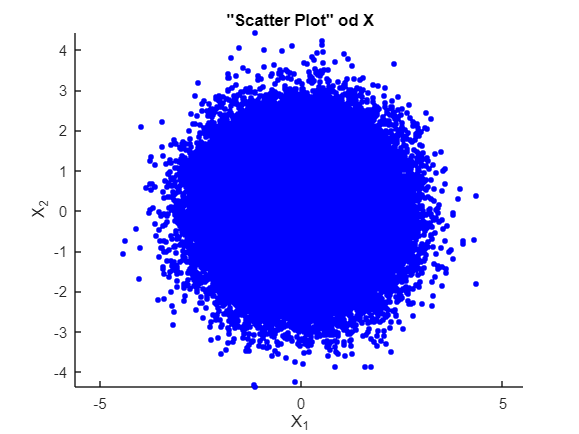


N = 100000; 
mean_X = 0; 
var_X = 1; 


X1 = mean_X + sqrt(var_X) * randn(N, 1); 
X2 = mean_X + sqrt(var_X) * randn(N, 1);


X = [X1, X2]';


a11_y = 1 / sqrt(2);
a21_y = sqrt(2);
a12_y = sqrt(5 / 2);
A_y = [a11_y, a12_y; a21_y, 0];


Y = A_y * X;


a12_z = -sqrt(3);
a22_z = 11 / (5 * sqrt(3));
a21_z = sqrt(29 / 3) / 5;
A_z = [0, a12_z; a21_z, a22_z];


Z = A_z * X;


figure;
scatter(X(1, :), X(2, :), 15, 'blue', 'filled');
title('"Scatter Plot" od X');
xlabel('X_1');
ylabel('X_2');
axis equal;

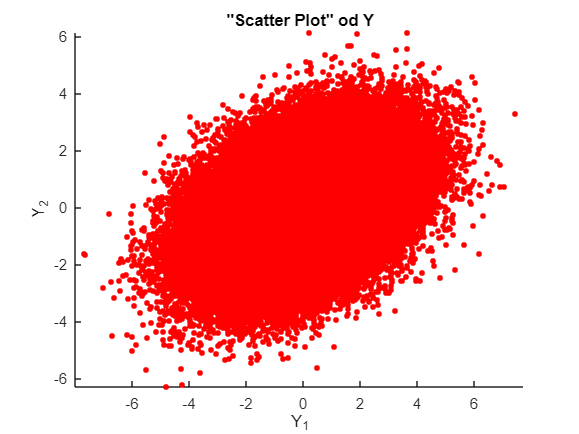



figure;
scatter(Y(1, :), Y(2, :), 15, 'red', 'filled');
title('"Scatter Plot" od Y');
xlabel('Y_1');
ylabel('Y_2');
axis equal;

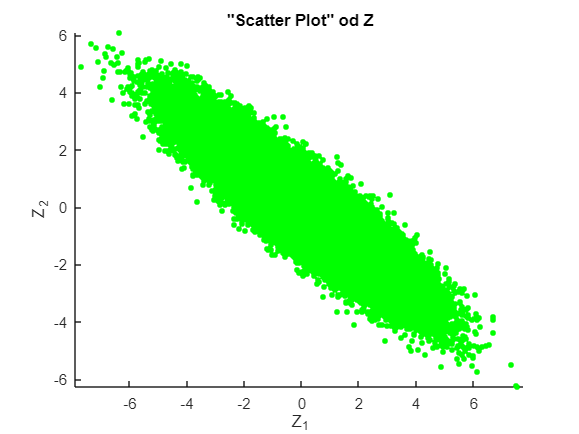



figure;
scatter(Z(1, :), Z(2, :), 15, 'green', 'filled');
title('"Scatter Plot" od Z');
xlabel('Z_1');
ylabel('Z_2');
axis equal;